This code Will run the autoExperimentAnalysis with all the logs available in batch process....

**remember to uncheck the singleTrial Analaysis in the AutoExperimentAnalysis file.**

clear ;
clc;


% Get the current working directory
cwd = pwd;

% Set the parent directory
allDataFolderPath = 'logs\firstSeries\';
[dirNames,dirPaths] = list_subfolders(allDataFolderPath)

dirNames = 1×12 cell array
    {'Alireza Alialsgari_21-11-2022_18-58-44'}    {'Alireza Aliasgari_11-01-2023_08-49-21'}    {'Alireza Ghaderi_07-02-2023_10-28-46'}    {'Alireza Ghaderi_07-11-2022_10-29-26'}    {'Alireza Ghaderi_07-11-2022_16-50-23'}    {'Alireza Ghaderi_08-01-2023_07-35-20'}    {'Alireza Ghaderi_10-02-2023_10-16-42'}    {'Alireza Ghaderi_12-02-2023_04-20-58'}    {'Alireza Ghaderi_12-02-2023_11-07-17'}    {'Alireza Ghaderi_13-02-2023_04-48-50'}    {'Alireza Ghaderi_14-02-2023_04-18-01'}    {'Alireza Ghaderi_17-01-2023_07-19-41'}


dirPaths = 1×12 cell array
    {'logs\firstSeries\Alireza Alialsgari_21-11-2022_18-58-44'}    {'logs\firstSeries\Alireza Aliasgari_11-01-2023_08-49-21'}    {'logs\firstSeries\Alireza Ghaderi_07-02-2023_10-28-46'}    {'logs\firstSeries\Alireza Ghaderi_07-11-2022_10-29-26'}    {'logs\firstSeries\Alireza Ghaderi_07-11-2022_16-50-23'}    {'logs\firstSeries\Alireza Ghaderi_08-01-2023_07-35-20'}    {'logs\firstSeries\Alireza Ghaderi_10-02-2023_10-16-42'}    {'logs\firstSeries\Alireza Ghaderi_12-02-2023_04-20-58'}    {'logs\firstSeries\Alireza Ghaderi_12-02-2023_11-07-17'}    {'logs\firstSeries\Alireza Ghaderi_13-02-2023_04-48-50'}    {'logs\firstSeries\Alireza Ghaderi_14-02-2023_04-18-01'}    {'logs\firstSeries\Alireza Ghaderi_17-01-2023_07-19-41'}


Test Dir
logs\firstSeries\Alireza Alialsgari_21-11-2022_18-58-44
Pilot Info
           name: 'Alireza Alialsgari'
         rating: 'Student'
       beginPVT: 477
         endPVT: 481
     hoursAwake: 6
     selfRating: 7
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [25026×22 table]
    description: {''}
           time: "21-Nov-2022 18:58:44"
        caffein: 'Low'

Before Test CAT
After Test CAT


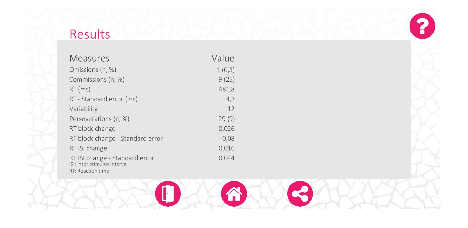

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris      aileron       elevator     throttle       rudder        roll         pitch        hdev         vdev       dmeNM        ias       altitude       vvi       heading       rpm      latitude    longitude
    __    ________________    _____    _____    ______    ______    ___________    __________    _________    __________    _________    _______

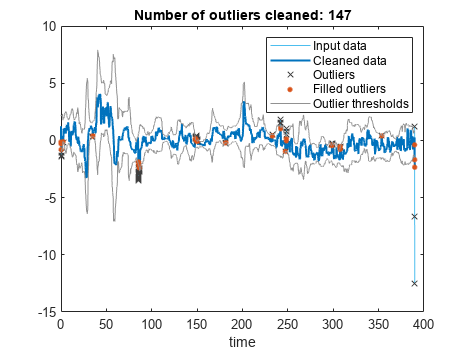

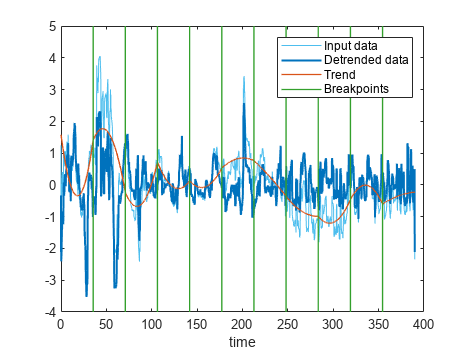

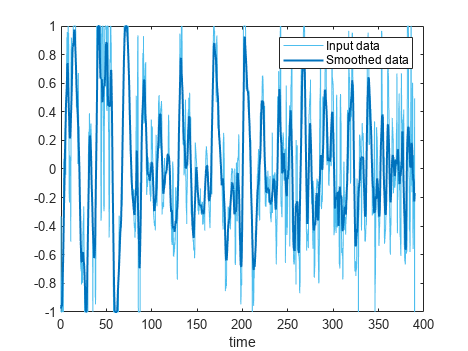

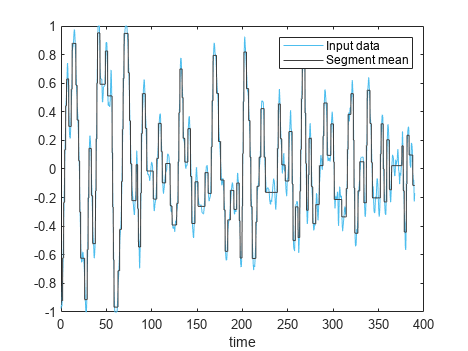

irisResult = struct with fields:
         meanFixation: 2.457112526539278
          varFixation: 3.663490754350620
    numFixationPerMin: 24.168305823997265


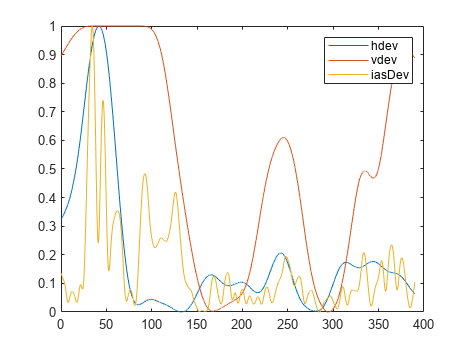

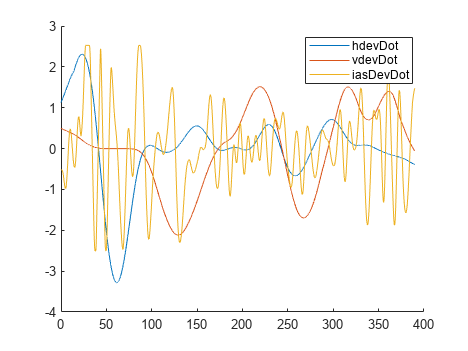

exceedanceResult = struct with fields:
    meanExceedance: 0.565115654588791


exceedanceResult = struct with fields:
    meanExceedance: 0.565115654588791
     varExceedance: 0.086508712916759


exceedanceResult = struct with fields:
            meanExceedance: 0.565115654588791
             varExceedance: 0.086508712916759
    detrendedVarExceedance: 0.063341097568622


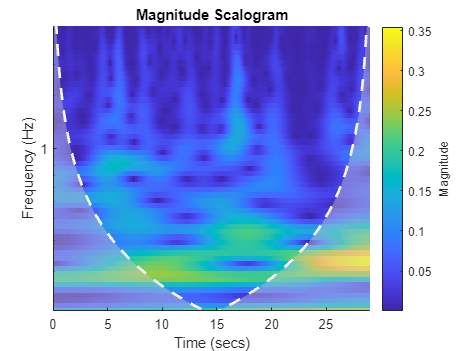



% Loop through the directory names and open autoExperimentAnalyzer.mlx
for bi = 1:length(dirNames)
    dirTest = dirNames{bi};
    dirPath = dirPaths{bi};
    scriptPath = fullfile(cwd, 'autoExperimentAnalyzer.mlx');
    %open(scriptPath);
    run(scriptPath);
    trialData(bi) = output;
end

%final data for all tests is gathered in trialData.






